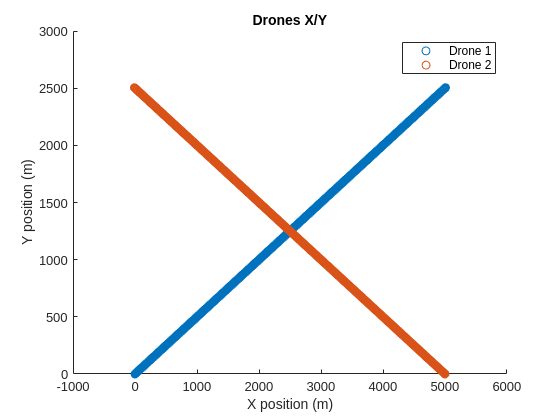

files = ["drone_1_pos.json", "drone_2_pos.json"];
drones = ["Drone 1", "Drone 2"];

X = [];
Y = [];
Z = [];
for file=files
    str = fileread(file);

    json = jsondecode(str);
    positions = json.positions;
    
    posx = [positions.x];
    posy = [positions.y];
    posz = [positions.z];

    X = [X, posx'];
    Y = [Y, posy'];
    Z = [Z, posz'];
end

scatter(X, Y);
title('Drones X/Y');
legend(drones);
xlabel('X position (m)');
ylabel('Y position (m)');

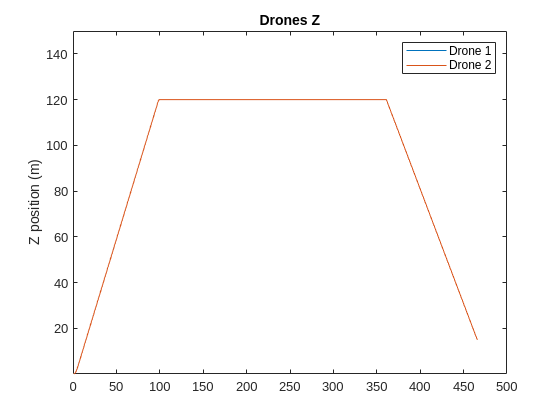


plot(Z);
title('Drones Z');
legend(drones);
Z = reshape(Z.',1,[]);
ylim([min(Z) max(Z)] .* 1.25);
ylabel('Z position (m)');

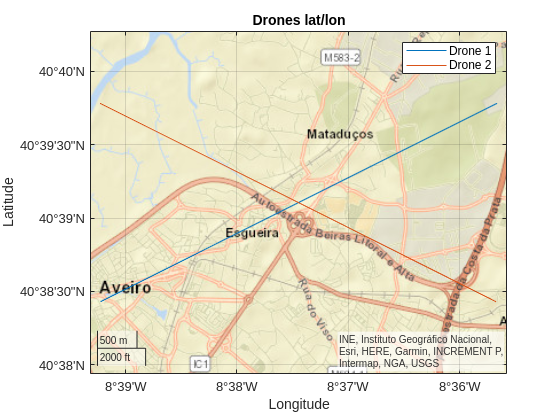


files_coords = ["drone_1_coords.json", "drone_2_coords.json"];
lat = [];
lon = [];
for file=files_coords
    str = fileread(file);

    json = jsondecode(str);
    coords = json.coordinates;
    
    lats = [coords.latitude];
    lons = [coords.longitude];

    lat = [lat, lats'];
    lon = [lon, lons'];
end

for i=1:length(files_coords)
    geoplot(lat(:, i), lon(:, i));
    hold on;
end
hold off;
title('Drones lat/lon');
legend(drones);
geobasemap streets;